# いろんな状況でポワソン方程式を高速に解く（追加）

- セルエッジ上で変数が定義される Dirichlet 境界条件

- セル中央で変数が定義される Dirichlet 境界条件

- セル中央で変数が定義される Neumann 境界条件

は別ファイルで紹介しましたが、もう1例追加します。3 の片方を Dirichet 条件にしたものです。

clear, close all
addpath('../functions/')

## 4. セルエッジ上で変数が定義される Dirichlet 境界＋ Neumann 境界の組み合わせ

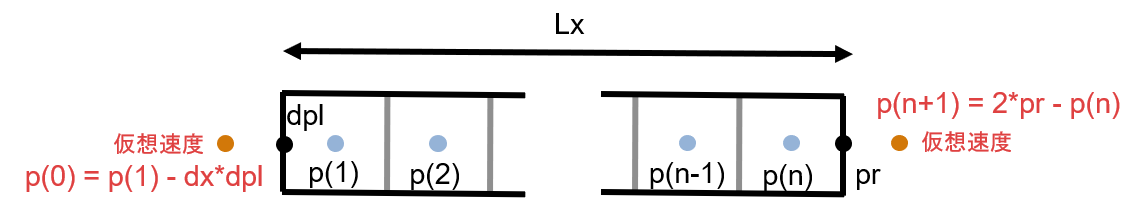

境界条件は両端で与えられ、解くべき変数は $n$ 個です。領域を $0 \le x \le 1$、境界条件を $dpl = 1$  $pr = 1$ とするととすると解は


$$p(x) = x^2/2 + x - 1/2$$
 

ですね。

### 離散式の確認

行列 ${\bf L}$ で境界条件が絡むところを確認すると、


$$\begin{array}{rl}
{L}p(1)&=\frac{p(0)-2p(1)+p(2)}{dx^2} =\frac{-p(1)+p(2)}{dx^2} - \frac{dpl}{dx} \\
{L}p(n)&=\frac{p(n-1)-2p(n)+2pr-p(n)}{dx^2} =\frac{p(n-1)-3p(n)}{dx^2} + \frac{2pr}{dx^2} \\
\end{array}$$


となります。はみ出た境界条件値 $bc_p$は右辺に移項します。

例えば $n = 6 $ だと以下のような行列になります。（実際はさらに $dx^2$ で割ったもの）

n = 6;
e = ones(n,1);
L = spdiags([e -2*e e],-1:1,n,n);
L(1,1) = -1;
L(end,end) = -3;
full(L)

ans =     -1     1     0     0     0     0
     1    -2     1     0     0     0
     0     1    -2     1     0     0
     0     0     1    -2     1     0
     0     0     0     1    -2     1
     0     0     0     0     1    -3


3 重帯行列です。

### 直接法

まずは直接法で解いてみます。

n = 30; % グリッド数は 30 で（なんでもいいです）
e = ones(n,1);
tmp = spdiags([e -2*e e],-1:1,n,n);
tmp(1,1) = -1;
tmp(end,end) = -3;

領域の設定して ${\rm L}$ を計算

dpl = 1; pr = 1; % Bounary Condition
Lx = 1; % Domain size
dx = Lx/n; % Grid size
xcenter = dx/2:dx:Lx-dx/2; % variable location
L1 = tmp/dx^2; % 

境界条件の値を右辺に移項して求解

rhs = ones(n,1); % 右辺
rhs(1) = rhs(1) + dpl/dx;
rhs(end) = rhs(end) - 2*pr/dx^2;
p_direct = L1\rhs;

プロット

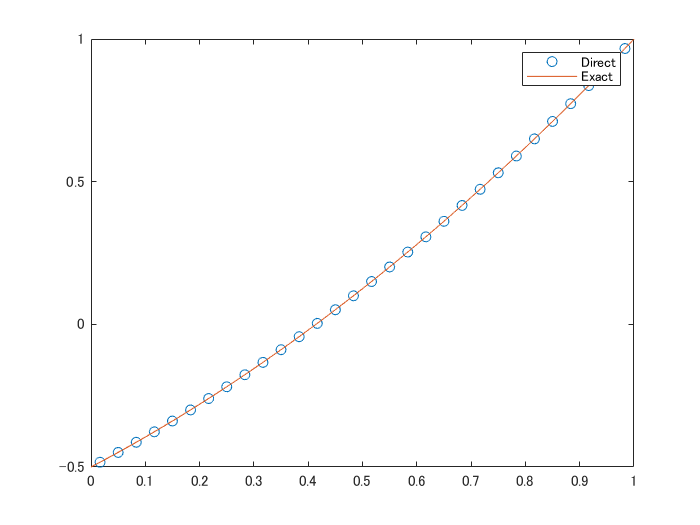

plot(xcenter,p_direct,'o')
hold on
fplot(@(x) x.^2/2 + x - 1/2, [0,1])
hold off
legend(["Direct","Exact"])

解けましたね。

### 離散コサイン変換の適用

こんどはコサイン変換でも FFTW の定義する [REDFT10 (DCT-IV)](http://www.fftw.org/fftw3_doc/1d-Real_002deven-DFTs-_0028DCTs_0029.html) を使います。DCT-IV の逆変換は DCT-IV です。

この変換は、例えば [ABCD] というデータを [D,C,B,A,A,B,C,D,-D,-C,-B,-A] と拡張して周期データとするイメージです。変数が定義されている位置からグリッド半分だけずれている位置にある Neumann 条件（左側）と Dirichlet 条件（右側）に合っています。

### 適用してみる

x 方向に対して離散コサイン変換を適用すると


$$p(x_i, y_j) = \sum_{k=0}^{N-1} \tilde{p}(k)  \cos{\left(\frac{\pi (i-1/2) (k-1/2)}{N}\right)},$$


となります。これをもともとの差分式に代入してすると


$$\frac{p(i-1) - 2 p(i) + p(i+1)}{\Delta x^2}
= \frac{1}{\Delta x^2} \sum_{k=0}^{N-1} \tilde{p}(k) \lambda_{x} \cos{\left(\frac{\pi (i-1/2) (k-1/2)}{N}\right)} }$$


ここで


$$\lambda_{x} = 2 \left( \cos\left(\frac{\pi (k-1/2)}{N}\right)-1 \right)$$


です。Modified Wavenumber と呼ぶあれです。


$$\frac{ \sin{(a (i+1/2))} - 2 \sin{(a (i-1/2)} + \sin{(a (i-3/2))} }{\sin{ (a (i-1/2)}} 
= 2 \left( \cos{ a }  - 1 \right).$$


こんな関係が役に立ちます。そうすると離散式は


$$\frac{\lambda_{x}}{\Delta x^2} \tilde{p}(k) = \tilde{f}(k),$$


と表すことができて、各 $\lambda_{x}$ の組み合わせの数だけ独立した式になりました。

この辺は先ほどとほとんど同じ。まず右辺を離散コサイン変換（DCT-IV）して、上の式で $\tilde{p}(k)$ を求めて、逆離散コサイン変換（DCT-IV）です。簡単！

やってみます。

rhshat = dct(rhs,"Type",4); % まず右辺に離散コサイン変換（DCT-IV）
kx = [0:n-1]'+0.5;
a = pi*kx/(n);
mw = 2*(cos(a)-1)/dx^2; % Modified Wavenumber
phat = rhshat./mw;
p_dst = idct(phat,"Type",4); % 離散コサイン変換（DCT-IV）で逆変換

先ほどの直接法でもとめた解との差を見てみると

norm(p_dst-p_direct)

ans = 8.7592e-15

いい感じですね。

プロットしてみると・・

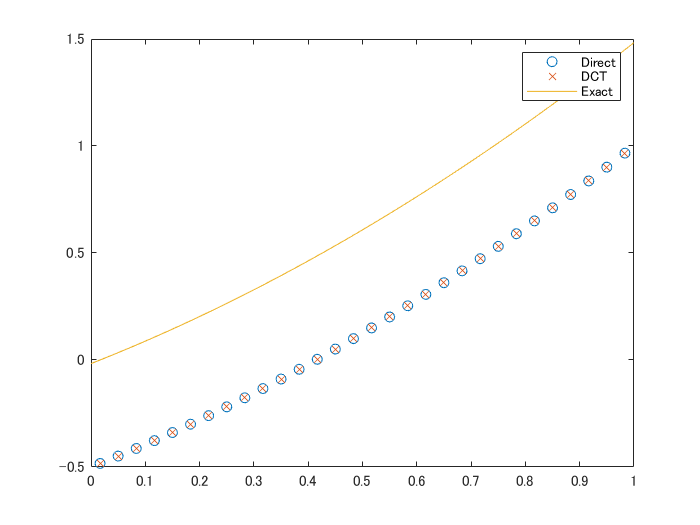

plot(xcenter,p_direct,'o')
hold on
plot(xcenter,p_dct,'x')
x1 = xcenter(1);
fplot(@(x) x.^2/2 + x - (x1^2/2+x1), [0,1])
hold off
legend(["Direct","DCT","Exact"])

予想通り定数分だけずれているように見えます。ずれを補正して誤差を確認してみます。

diffp = p_dct(1)-p_direct(1);
norm(p_direct-p_dct+diffp)

ans = 8.3340e-15

解けています。

## まとめ

- セル中央で変数が定義される Neumann 境界＋Dirichlet 境界条件：離散コサイン変換（DCT-IV）